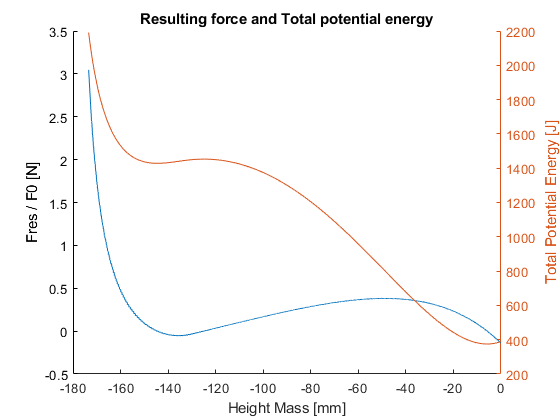

load("best_spiral.mat"); %loading in the final shape 

n_steps = 2000; %shape resolution

### Initial stable condition

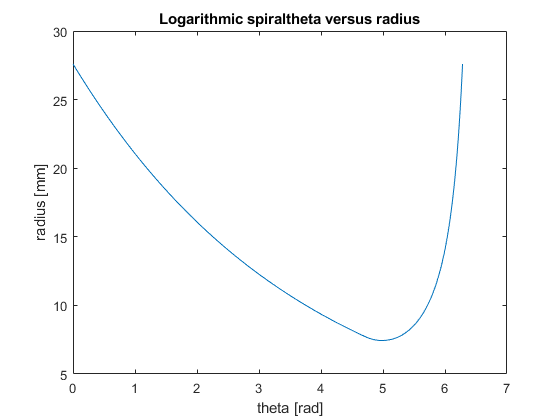

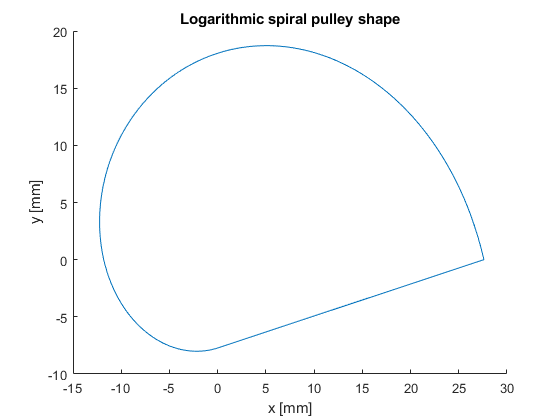

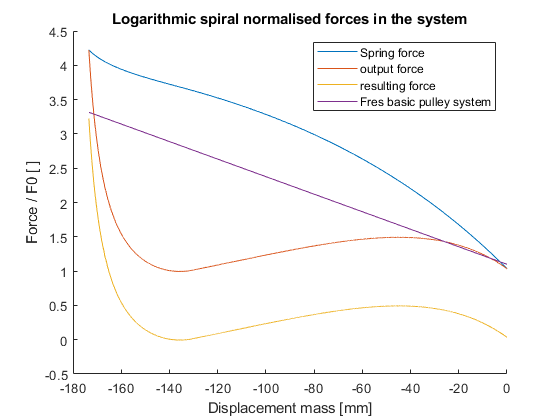

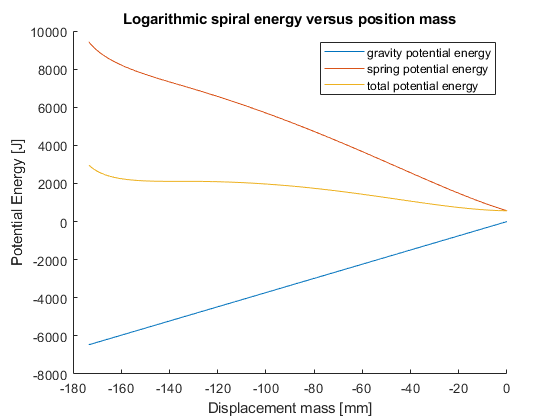

spiral =   spiral with properties:

                   r1: 10
                   r2: 27.6000
                   F0: 37.2780
                    k: 1.3150
                 name: 'Logarithmic spiral'
                    S: []
                    r: [1×1301 double]
                theta: [1×1301 double]
                    x: [1×1301 double]
                    y: [1×1301 double]
    spiral_max_stroke: 173.4159
          curve_angle: 1.3069
                 x_m2: 173.4159
                  x_m: [1×2001 double]
                  x_s: [1×2001 double]
                   rs: [1×2001 double]
                  phi: [1×2001 double]
        spring_offset: 1
                   Fm: [1×2001 double]
                   Fs: [1×2001 double]
                 Fres: [1×2001 double]
           Fm_control: [1×2001 double]
                   Eg: [1×2001 double]
                   Es: [1×2001 double]
                 Etot: [1×2001 double]


spiral = best_spiral.plot_all(n_steps,best_spiral.spring_offset) %genenerating and plotting initial condition

## Step 1: lowering and activiation first stage

In this first step the mass is lowerd by it being pushed down by the guiding rails. At the end of the rails it has to disconnect by itself by the fact that the equilibrium position is lower than the guiding rails

Important parts about the force balance and potential energy

- Troughout the long stroke motion we must have positive pressure, negative pressure will mean disengagement of the guides

- When we reach the final end position we want to crossover to negative force -> This way the mass will lower itself 

- We want the local equilibrium point to be 10 mm lower than the crossover point (the point where the guides will be disengaged)

- Initial position

- Crossover point

- Equilibrium position

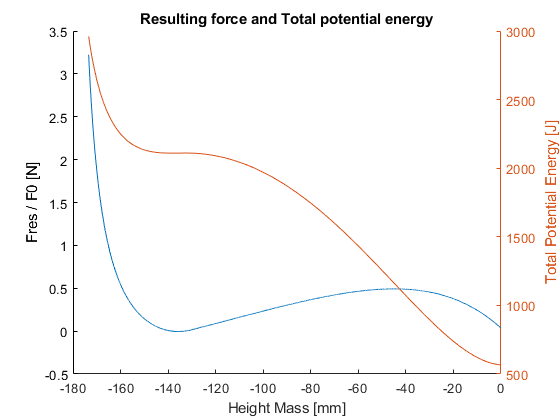

Arrays have incompatible sizes for this operation.

Related documentation

spiral = spiral.complete_analysis(n_steps,spiral.spring_offset);
fig = spiral.plot_force_energy();

lowered_spiral = spiral.complete_analysis(n_steps,spiral.spring_offset-10);
fig = lowered_spiral.plot_force_energy();
x0 = find_zero(lowered_spiral.x_m, lowered_spiral.Fres) %finding zeros

x0 =   -14.1643 -116.7643 -147.9753


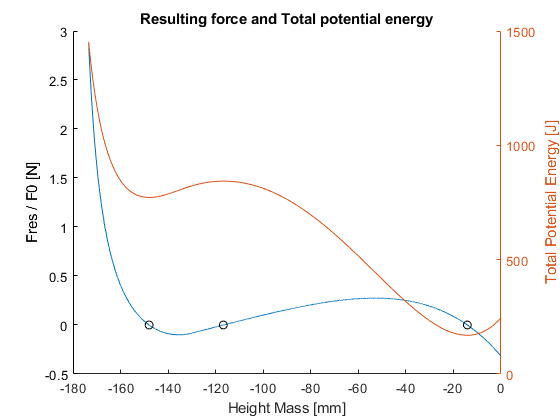


yyaxis left %setting y axis back to left
scatter(x0,zeros(1,length(x0)))

### Potential optimization

To minimize pressure on the guiding rails the spring tension can be adjusted trough the motion such that is is sufficiently low

function x0 = find_zero(x,y)
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Approximate Zero-Crossing Indices Of Argument Vector
    dy = zci(y);                                                            % Indices of Approximate Zero-Crossings
    for k1 = 1:size(dy,1)-1
        b = [[1;1] [x(dy(k1)); x(dy(k1)+1)]]\[y(dy(k1)); y(dy(k1)+1)];      % Linear Fit Near Zero-Crossings
        x0(k1) = -b(1)/b(2);                                               % Interpolate ;Exact’ Zero Crossing
        %mb(:,k1) = b;                                                       % Store Parameter Estimates (Optional)
    end
end
